# List Selector (single pane)

The List Selector widget is intended for adding items to a list from a known set. You can optionally enable reordering the items, and add custom buttons.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 250 215]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

listWidget = wt.ListSelector(gridObj);
listWidget.ValueChangedFcn = @(src,evt)disp(evt);

Set the available items to choose from:

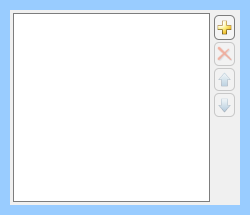

listWidget =   ListSelector with properties:

               ButtonPushedFcn: ''
               ValueChangedFcn: @(src,evt)disp(evt)
    HighlightedValueChangedFcn: ''

                         Items: ["California"    "Massachusetts"    "Michigan"    "Texas"]
                     ItemsData: [1×0 double]
               AllowDuplicates: off
                     AddSource: Items
                    ValueIndex: []
                         Value: [1×0 string]
              HighlightedValue: [1×0 string]
                   ButtonWidth: 25
                   UserButtons: [1×1 ButtonGrid]
                   ButtonColor: [0.9600 0.9600 0.9600]
                    FieldColor: [1 1 1]

                      Position: [11 11 230 195]
                         Units: 'pixels'

  Show 

listWidget.Items = ["California","Massachusetts","Michigan","Texas"]

Set the currently selected items:

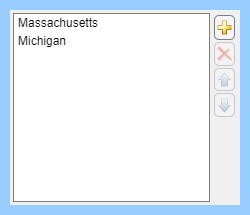

listWidget.Value = ["Massachusetts","Michigan"];

Programmatically set which item is currently highlighted:

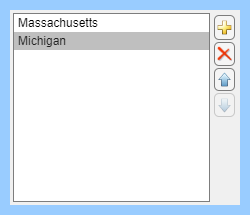

listWidget.HighlightedValue = "Michigan";

You can also add your own custom buttons:

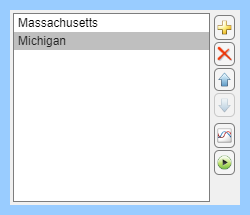

listWidget.ButtonPushedFcn = @(src,evt)disp(evt);
listWidget.UserButtons.Icon = ["plot_24.png","play_24.png"];
listWidget.UserButtons.ButtonHeight = {25 25};

*Copyright 2020-2025 The MathWorks, Inc.*